# Imaging with uSARA

## Description

Unconstrained Sparsity Averaging Reweighted Analysis algorithm, dubbed as `uSARA,` is the unconstrained counterpart of the `SARA` algorithm. It is underpinned by differentiable data fidelity term, redundant wavelet prior and the forward-backward algorithmic structure for solving inverse imaging problem. The details of the algorithm are discussed in the following papers.

- [1] Terris, M., Dabbech, A., Tang, C., & Wiaux, Y., [Image reconstruction algorithms in radio interferometry: From handcrafted to learned regularization denoisers](https://doi.org/10.1093/mnras/stac2672). *MNRAS, 518*(1), 604-622.

- [2] Repetti, A., & Wiaux, Y., [A forward-backward algorithm for reweighted procedures: Application to radio-astronomical imaging](https://doi.org/10.1109/ICASSP40776.2020.9053284). *IEEE ICASSP 2020*, 1434-1438, 2020.

- [3] Wilber, A. G., Dabbech, A., Jackson, A., & Wiaux, Y., [Scalable precision wide-field imaging in radio interferometry: I. uSARA validated on ASKAP data](https://doi.org/10.1093/mnras/stad1351). *MNRAS, 522*(4), 5558-5575, 2023.

In this tutorial, we focus on [a MATLAB implementation of uSARA](https://github.com/basp-group/uSARA) for small scale monochromatic intensity imaging in SII, from the environment setup, to imaging of simulated radio-interferometric data.

## Inverse Problem

The RI imaging inverse problem can be formulated as:

$\mathbf{\mathit{y}} = \mathbf{\Phi} \overline{\mathbf{\mathit{x}}} + \mathbf{\mathit{n}}$,

where $\mathbf\mathit{y}}$$\in \mathbb{C}^M$ is the measurement vector, $\overline{\mathbf{\mathit{x}}}$$\in \mathbb{R}^N$ is the unknown radio image, $\mathbf{\Phi}$$\in \mathbb{C}^{N \times M}$ is the measurement operator corresponding to incomplete Fourier sampling, and $\mathbf\mathit{n}}$$\in \mathbb{C}^M$ is the noise. Our task is reconstructing $\overline{\mathbf{\mathit{x}}}$ from the measurement $\mathbf\mathit{y}}$.

## uSARA's iteration structure

uSARA is underpinned by the forward-backward algorithmic structure from optimisation theory. The iteration structure takes a two step-update: a forward step enforcing data fidelity, followed by a backward denoising step.

$\mathbf{\mathit{x}}_{i+1} = \mathrm{prox}_{\gamma g} \left (  \mathbf{\mathit{x}}_{i} - \delta \mathbf{\Phi}^{\dagger}  \left ( \mathbf{\Phi} \mathbf{\mathit{x}}_{i} - \mathbf{\mathit{y}} \right ) \right)$,

where $g$ represents the SARA prior with the positivity constrained, $\delta \in [0, 2/ \| \mathbf{\Phi} \|_{\mathrm{S}}^2]$ is a step size, which depends on the spectral norm of the measurement operator. $\| \cdot \|_{\mathrm{S}}$ stands for the spectral norm. Here we fixed it to $\delta = 1.98 / \| \mathbf{\Phi} \|_{\mathrm{S}}^2$. And $\gamma$ is the regularization parameter controlling the soft thresholding level in the wavelet domain.

The choice of $\gamma$ is crucial for best results. In fact, when $\gamma$ is too large, the reconstructed image will be very smooth. In the opposite case, the reconstructed image will be grainy and noisy. In [1], we proposed that the regularisation parameter should be linked to the noise level in the target image, which can be estimated from the measurement data as

$\sigma = \frac{\tau}{\sqrt{2 \| \mathbf{\Phi} \|_{\mathrm{S}}^2 }}$,

where $\tau$ is the standard deviation of $\mathbf{\mathit{n}}$. Then $\gamma$should be set to $\gamma = \sigma / \delta$. 

This heuristic has shown to be effective both in simulation and on real data. However, in some cases an adjustment of its value  - within one order of magnitude -  may be necessary for best results. The adjusting factor is by default set to 1 and can be fine-tuned if needed. Readers can refer to this [README](https://github.com/basp-group/AIRI/blob/main/config/README.md) for more details.

## Clone Repository

You can clone the repository to the current directory by running the command below.

!git clone --recurse-submodules https://github.com/basp-group/uSARA.git
cd ./uSARA

The `--recurse-submodules` flag is required so that the required sub-modules [`RI-measurement-operator`](https://github.com/basp-group/RI-measurement-operator) and [`SARA-dictionary`](https://github.com/basp-group-private/SARA-dictionary/tree/master) will be cloned at the same time.

## Dependencies

To run this repository, your MATLAB version should be higher than R2019b. The scripts below will check whether the required toolboxes have been installed or not.

list_tb = matlab.addons.installedAddons().Name;
if ~ismember(list_tb, "Parallel Computing Toolbox")
    error("Please install Parallel Computing Toolbox!\n")
elseif ~ismember(list_tb, "Wavelet Toolbox")
    error("Please install Wavelet Toolbox!\n")
else
    fprintf("All set!\n")
end

If you need to install missing toolboxes, you can go to the "HOME" tab of MATLAB. Then in "Add-Ons", click "Get Add-Ons" and search for the name of the toolbox in question.

## Test Dataset

In this tutorial, we provide a test dataset composed of a ground truth image in **.fits** format and associated measurement file in **.mat** format. The ground truth is an image of the radio galaxy 3c353. First, let us visualise the ground truth image.

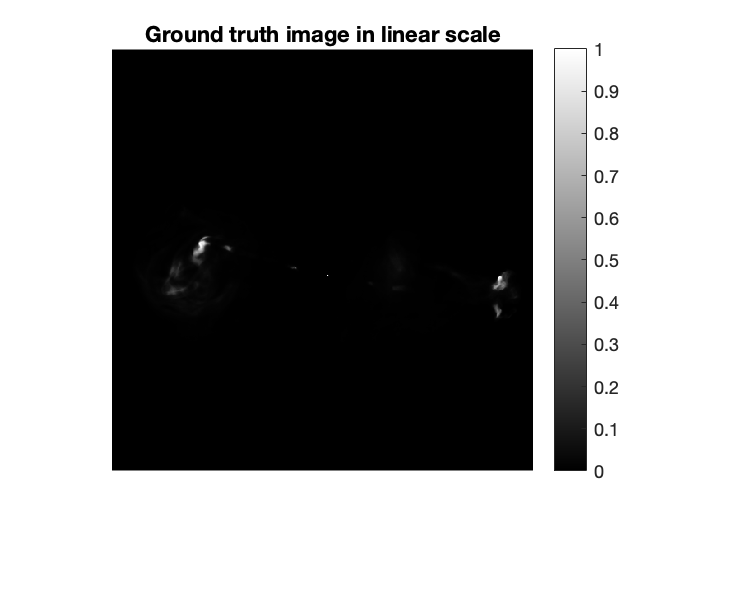

img_gdth = fitsread(fullfile("data","3c353_gdth.fits"));
figure
imshow(img_gdth)
colorbar
title("Ground truth image in linear scale")

Given the large dynamic range of the ground truth, only bright features are visible in linear scale. For a better visualisation, we map the pixels intensities in image $\mathbf{\mathit{x}}$ to the logarithmic scale using the equation below:


$$\textrm{rlog}(\mathit{\mathbf{x}})={\mathit{\mathbf{x}}}_{\max } \log_a (\frac{a}{{\mathit{\mathbf{x}}}_{\max } }\mathit{\mathbf{x}}+1)\;,$$


where $a$ corresponds to the dynamic range of the ground truth $\mathbf{\mathit{x}}$ and ${\mathit{\mathbf{x}}}_{\max }$ is the maximum intensity. In this case, $a = 2.5 \times10^3$ and ${\mathit{\mathbf{x}}}_{\max } =1\ldotp 0$.

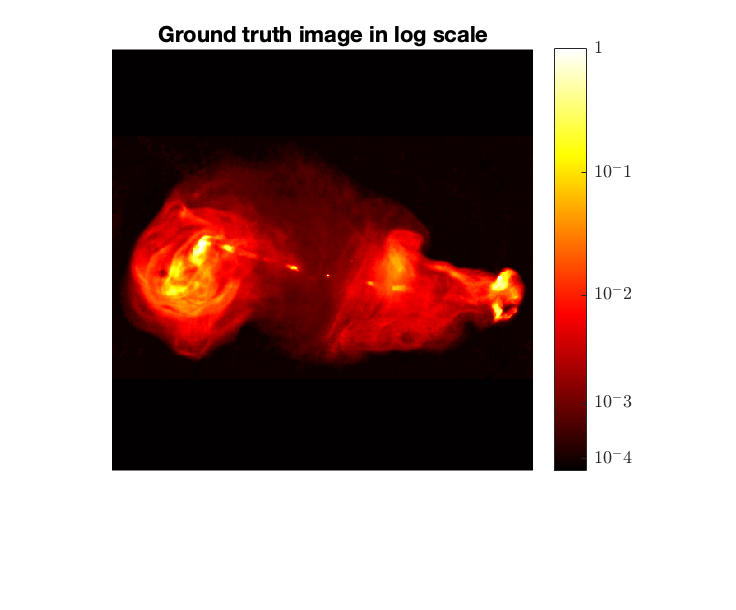

rlog = @(x, a) log10(a .* x + 1) ./ log10(a);
img_gdth_log = rlog(img_gdth, 2500);
figure
imshow(img_gdth_log, 'Colormap', colormap('hot'))
cb = colorbar;
ticks = rlog([1e-4, 1e-3, 1e-2, 1e-1, 1.0], 2500);
ticks(end) = 1;
cb.Ticks = ticks;
cb.TickLabels = {"$10^-4$", "$10^-3$", "$10^-2$", "$10^-1$", "$1$"};
cb.TickLabelInterpreter = 'latex';
title("Ground truth image in log scale")

The test measurement file  in `.mat `associated with the above ground truth can be loaded via the command below.

meas = load(fullfile("data/3c353_meas_dt_1_seed_0.mat"))

meas = struct with fields:
          frequency: 1.0000e+09
                  y: [201600×1 double]
                  u: [201600×1 double]
                  v: [201600×1 double]
                  w: [201600×1 double]
                 nW: [201600×1 double]
             nWimag: []
    maxProjBaseline: 2.5948e+04


The expected fields are listed below.

- "**y**" is a measurement/data  vector.

- "**u**" is a vector containing $u$ coordinates of the sampling position in units of the observation wavelength.

- "**v**" is a vector containing $v$ coordinates of the sampling position in units of the observation wavelength.

- "**w**" is a vector containing $w$ coordinates of the sampling position in units of the observation of wavelength.

- "**nW**" is a vector containing the so-called natural weights, corresponding to the inverse of the noise standard deviation. The vector constitutes a whitening operator to be applied to the data and injected in the measurement operator.

- "**nWimag**" is a vector containing the imaging weights if available, compensating for the non-uniform Fourier sampling and enhancing the effective resolution of the observations. The vector is **optional** and can be computed directly in the uSARA code.

- "**frequency**" is the observation frequency (in Hz).

- "**maxProjBaseline**" is the maximum projected baseline in  units of the observation wavelength, formally it equals to $\mathrm{max} \left \{ \sqrt{\mathbf{\mathit{u}}^2 + \mathbf{\mathit{v}}^2 } \right \}$.

In the context of narrow field RI imaging, the $w$ coordinates will not be considered in the measurement operator. The collection of the points $(\mathbf{\mathit{u}}, \mathbf{\mathit{v}})$ constitutes the Fourier sampling pattern also known as the $uv$-coverage. Meanwhile, we also provide example scripts for [generating synthetic measurement files](https://github.com/basp-group/RI-measurement-operator/blob/master/example_sim_ri_data.m) and [converting Measurement Sets (MS) to the **.mat **files](https://github.com/basp-group/AIRI/tree/main/ms2mat) with the same format.

## Image Reconstruction

The uSARA imager is launched with function `run_imager`. This function has a mandatory input, which is the path of a configuration file, where all the parameters involved in the imaging process are defined. An example configuration file, `./config/usara_sim.json`, is provided. We kindly point the readers to this [README](https://github.com/basp-group/uSARA/blob/main/config/README.md) for more information about the fields in this file. The function `run_imager` also accepts **optional** name-argument to overwrite corresponding fields in the configuration file. 

Here, we'll reconstruct the image from the example test dataset. The target image size is $512 \times 512$, which is the same as the size of ground truth image. The image pixel size (in the unit of arcsec) can also be specified through both configuration file and the input argument. Otherwise, it will be calculated from the value of the max projected baseline and the super resolution factor as

$imPixelSize = \frac{180}{\pi} \times \frac{3600}{superresolution \times 2 \times maxProjBaseline}$.

The super resolution factor in this case is `1.0`, which means that the Fourier sampling is done at the same spatial bandwidth as the ground truth image. For the data weighting scheme, we only consider natural weighting in this example.

The full imaging command is shown below. It should take less an hour to finish.

run_imager("./config/usara_sim.json", ...                   path of the configuration file
    'srcName', "example", ...                               name of the target src used for output filenames
    'dataFile', "./data/3c353_meas_dt_1_seed_0.mat", ...    path of the measurement file
    'resultPath', "./results", ...                          path where the result folder will be created
    'imDimx', 512, ...                                      horizontal number of pixels in the final reconstructed image
    'imDimy', 512, ...                                      vertical number of pixels in the final reconstructed image
    'superresolution', 1.0, ...                             used if pixel size not provided
    'groundtruth', "./data/3c353_gdth.fits", ...            path of the groundtruth image when available, used to calculate SNR at the end
    'runID', 0 ...                                          identification number of the imaging run used for output filenames
  )

In the output log information, we can see that the heuristic noise level of the target image is approximately $3.7 \times 10^{-4}$. 

The dirty image of the example test set, which is defined as $\mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\mathit{y}} \right \} / \kappa$, where $\kappa$ is the maximum intensity of PSF, and $\kappa = \mathrm{max} \left \{ \mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\Phi} \mathbf{\mathit{\delta}} \right \} \right \}$ with $\mathbf \mathit \delta$ as Dirac delta image.

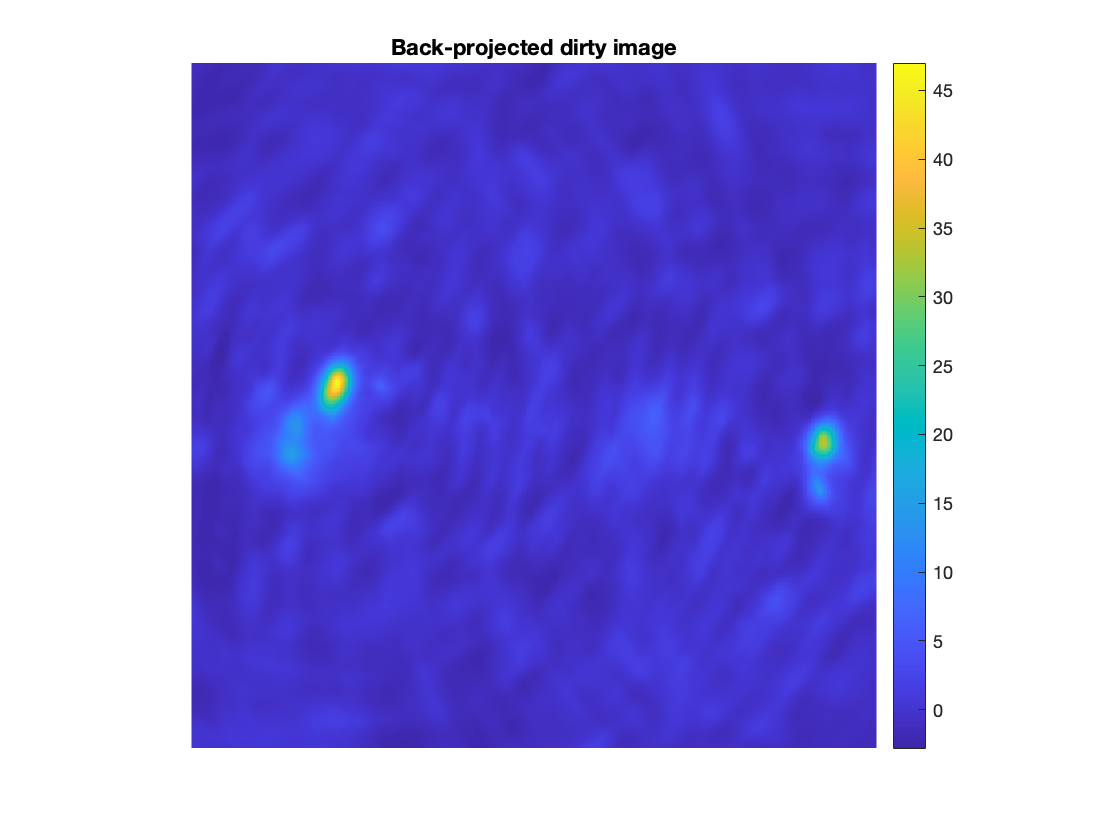

The script will yield reconstruction$\widetilde{\mathbf{\mathit{x}}}$shown below. The SNR is around `24.0 dB`. The SNR of the log scale image $\mathrm{rlog} ( \mathbf{\mathit{\widetilde{x}}} )$ is `21.3 dB`.

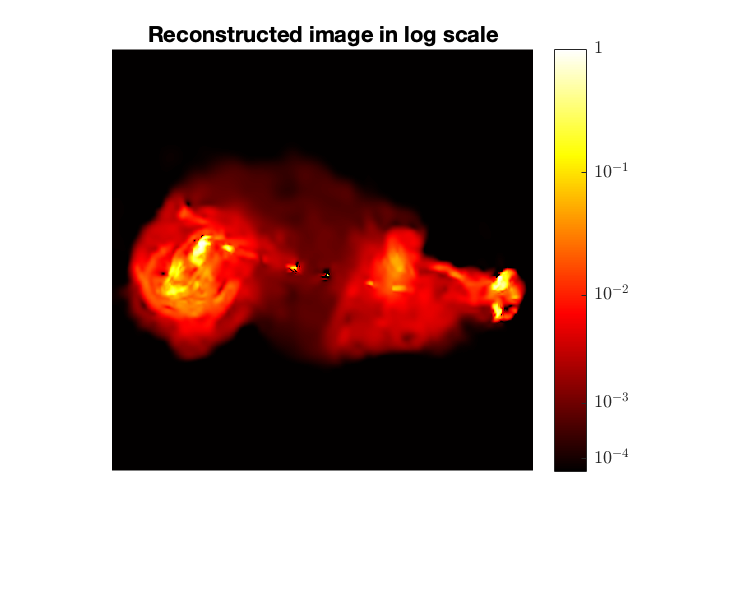

The residual dirty image is shown below and defined as $\left ( \mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\mathit{y}} \right \} - \mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\Phi} \widetilde{\mathbf{\mathit{x}}} \right \} \right ) 
/ \kappa$.

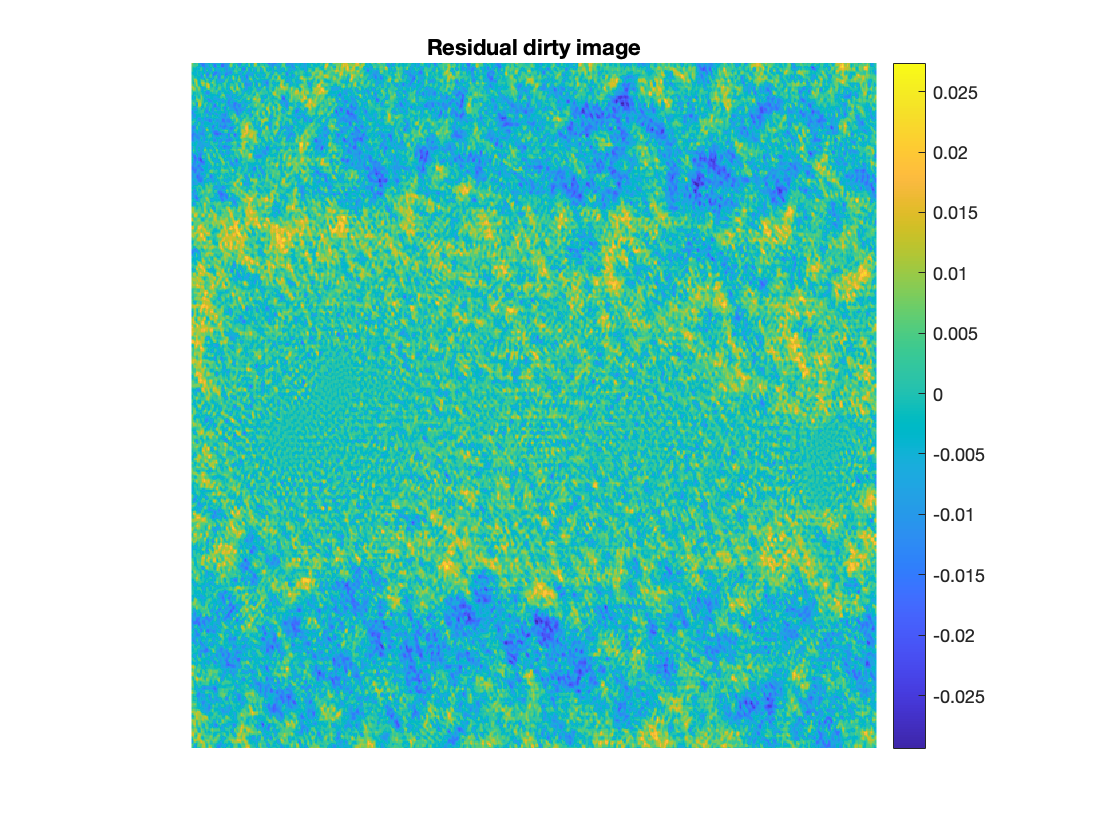

## Additional Functionalities

The code supports data-weighting schemes during imaging (uniform or Briggs weighting). It  provides the functionality to compute the imaging weights if not available in the input data file.